%% CONSTANTS %%

H = 6.62607004*10^-34; % m2kg/s
C = 299792458; % m/s

%% Sample's Characteristics %%

global a;
global b;
global c;
global atomPositions;

% Unit Cell size, in Angstrom's
a = 4.1*10^-10;
b = 4.1*10^-10;
c = 4.1*10^-10;

% Atomic positions in unit cell
atomPositions = [0,0,0;0.5,0.5,0.5];

%% X-Ray Beam Properties %%

beamkeV = 7; %Enter value in keV
lambda = (H*C)/(beamkeV*(6.2415096471204*10^15)^-1); % m

%% XRD %%
% n*lambda = 2*d*sin()

thetaData = [];
planeData = [];
% Calculate angle for different (hkl) planes
for h = 0:5
    for k = 0:5
        for l = 0:5
            d = dspacing(h,k,l); 

            if lambda/(2*d) <= 1 && lambda/(2*d) >= -1                
                theta = asind(lambda/(2*d));
                
                atoms = zeros(size(atomPositions,1),1);
                for i1 = 1:length(atoms)
                    atoms(i1) = exp(2*pi*1i*(h*atomPositions(i1,1)+k*atomPositions(i1,2)+l*atomPositions(i1,3)));
                end
                f = abs(real(sum(atoms)));
                if f == 0
                    continue;
                end

                thetaData = [thetaData, theta];
                planeData = [planeData; h,k,l];
            end           
        end
    end
end

data = [planeData(2:end,:),2*thetaData(2:end)'];
array2table(data,"VariableNames",{'h', 'k', 'l', '2theta'})

ans = 40×4 table
    h    k    l    2theta
    _    _    _    ______

    0    0    2    51.189
    0    0    4    119.54
    0    1    1    35.573
    0    1    3    86.165
    0    2    0    51.189
    0    2    2    75.315
    0    2    4    150.03
    0    3    1    86.165
    0    3    3    132.81
    0    4    0    119.54
    0    4    2    150.03
    1    0    1    35.573
    1    0    3    86.165
    1    1    0    35.573
    1    1    2    63.888
    1    1    4    132.81


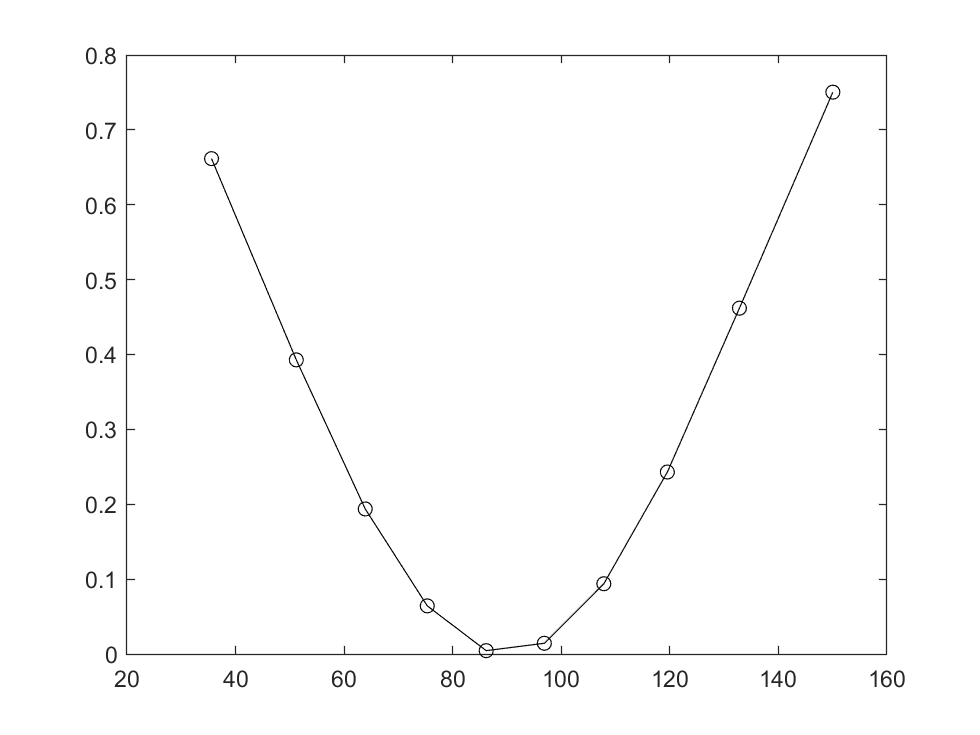

[V,~,u] = unique(thetaData(2:end)*2);
count = accumarray(u,1);

plot(V,cosd(V).^2,'ok-')

function factors = factor(h1,k1,l1)
    global atomPositions;
    atoms = zeros(size(atomPositions,1),1);
    for i1 = 1:length(atoms)
        atoms(i1) = exp(2*pi*1i*(h1*atomPositions(i1,1)+k1*atomPositions(i1,2)+l1*atomPositions(i1,3)));
    end
    
    factors = sum(atoms);
end

function spacing = dspacing(h1,k1,l1)
    global a;
    global b;
    global c;
    spacing = sqrt((h1^2/a^2+k1^2/b^2+l1^2/c^2)^-1);
end